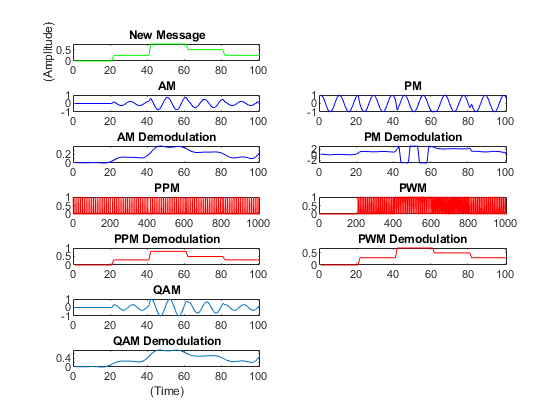

clear 
close all


        %-----------------------------------
        %-------- AM in class room ---------
        %-----------by Teacher--------------
        
samplingRate = 10000;                   % sampling-rate or sampling-frequency  , Fs = 10000
%samplingRate = 1000;                   % sampling-rate or sampling-frequency  , Fs = 10000

carrierFrequency = 1000;
%t = 0 : 1/samplingRate : 1;           

x1 = zeros(1,21);                   % value 0 
x2 = ones(1,20);                    % value 1 
x3 = 2*x2;                          % value 2 
x4 = 3*x2;                          % value 3  
x5 = zeros(1,20);                   % value 0 

x1(x1==0) = 0    ;
x2(x2==1) = 0.25 ;
x3(x3==2) = 0.5  ;
x4(x4==3) = 0.75 ;
x5(x5==0) = 0    ;

        %-----------------------------------
        %--------- New Application ---------
        %-----by Theerapong Kulawong--------

%newMessage = ["00","01","10","11","00"];
%newMessage = ["00","01","10","10","11"];
newMessage = ["00","01","11","10","01"];
if ( strcmp(newMessage(1),"00") )
       newSignal = x1; %0
elseif ( strcmp(newMessage(1),"01") )
       newSignal = x2; %1
elseif ( strcmp(newMessage(1),"10") )
       newSignal = x3; %2
else  
       newSignal = x4; %3
end

for i=2 : 5
   if     ( strcmp(newMessage(i),"00") )
       newSignal = cat(2,newSignal,x5); %0
   elseif ( strcmp(newMessage(i),"01") )
       newSignal = cat(2,newSignal,x2); %1
   elseif ( strcmp(newMessage(i),"10") )
       newSignal = cat(2,newSignal,x3); %2
   else  
       newSignal = cat(2,newSignal,x4); %3 
   end
end
subplot(7,2,1); plot(newSignal,'g');  title('New Message');  ylabel('(Amplitude)');


        %-----------------------------------
        %---------------- AM ---------------
        %-----------------------------------

newAM = modulate(newSignal,carrierFrequency,samplingRate,'AM'); 
subplot(7,2,3); plot(newAM,'b'); title('AM');

demodAM = demod(newAM,carrierFrequency,samplingRate,'AM'); 
subplot(7,2,5); plot(demodAM,'b'); title('AM Demodulation');



        %-----------------------------------
        %----------------- PM --------------
        %-----------------------------------

newPM = modulate(newSignal,carrierFrequency,samplingRate,'PM'); 
subplot(7,2,4); plot(newPM,'b'); title('PM');
      
demodPM = demod(newPM,carrierFrequency,samplingRate,'PM'); 
subplot(7,2,6); plot(demodPM,'b'); title('PM Demodulation');
       
        %-----------------------------------
        %--------------- PPM ---------------
        %-----Pulse-position modulation-----
        

modPPM = modulate(newSignal,carrierFrequency,samplingRate,'ppm');
subplot(7,2,7); plot(modPPM,'r');title("PPM");

demodPPM=demod(modPPM,carrierFrequency,samplingRate,'ppm');
subplot(7,2,9); plot(demodPPM,'r');title("PPM Demodulation");



        %-----------------------------------
        %---------- PWM Modulation----------
        %-------Pulse-width modulation------
        
modPWM = modulate(newSignal,carrierFrequency,samplingRate,'pwm','centered') ;
subplot(7,2,8);  plot(modPWM,'r');    title('PWM');

demodPWM = demod(modPWM,carrierFrequency,samplingRate,'pwm','centered') ;
subplot(7,2,10);  plot(demodPWM,'r');    title('PWM Demodulation');



        %-----------------------------------
        %---------- QAM Modulation ---------
        %-Quadrature amplitude modulation---
        
newQAM = modulate(newSignal,carrierFrequency,samplingRate,'qam',newSignal); 
subplot(7,2,11); plot(newQAM); title('QAM');

demodQAM = demod(newQAM,carrierFrequency,samplingRate,'qam',newSignal); 
subplot(7,2,13); plot(demodQAM); title('QAM Demodulation');



xlabel('(Time)');